# Sample 5-2

## 周波数解析

単変量循環畳み込み

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Fourier analysis

Univariate circular convolution

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 入力信号 $\{u[n]\}_n
$ 

(Input signal $\{u[n]\}_n
$)

% Input x[n]
u = [1 2 3];

### 線形シフト不変システムのインパルス応答 $\{h[n]\}_n
$ 

(Impulse response of a linear shift-invariant system $\{h[n]\}_n
$)

% Impulse response h[n]
h = [1 1 1]/3;

### 周期 $N$ の循環畳み込みの出力応答$\{v[n]\}_n
$ 

(Output response $\{v[n]\}_n
$ of circular convolution with period $N$ )

循環畳み込み演算 (Circular convolution)

        
$$\{v[n]\}_n=\{h[n]\}_n \bigcirc \{u[n]\}_n = \sum_{k=-\infty}^{\infty}u[k]\{h[(\!(n-k)\!)_N]\}_n
$$


% Setting the period N
nZeroPadding =0;
nPeriod = max(length(u),length(h)) + nZeroPadding;

% Output v[n]
v = cconv(h,u,nPeriod);

### 畳み込み演算との比較

(Comparison with convolution)

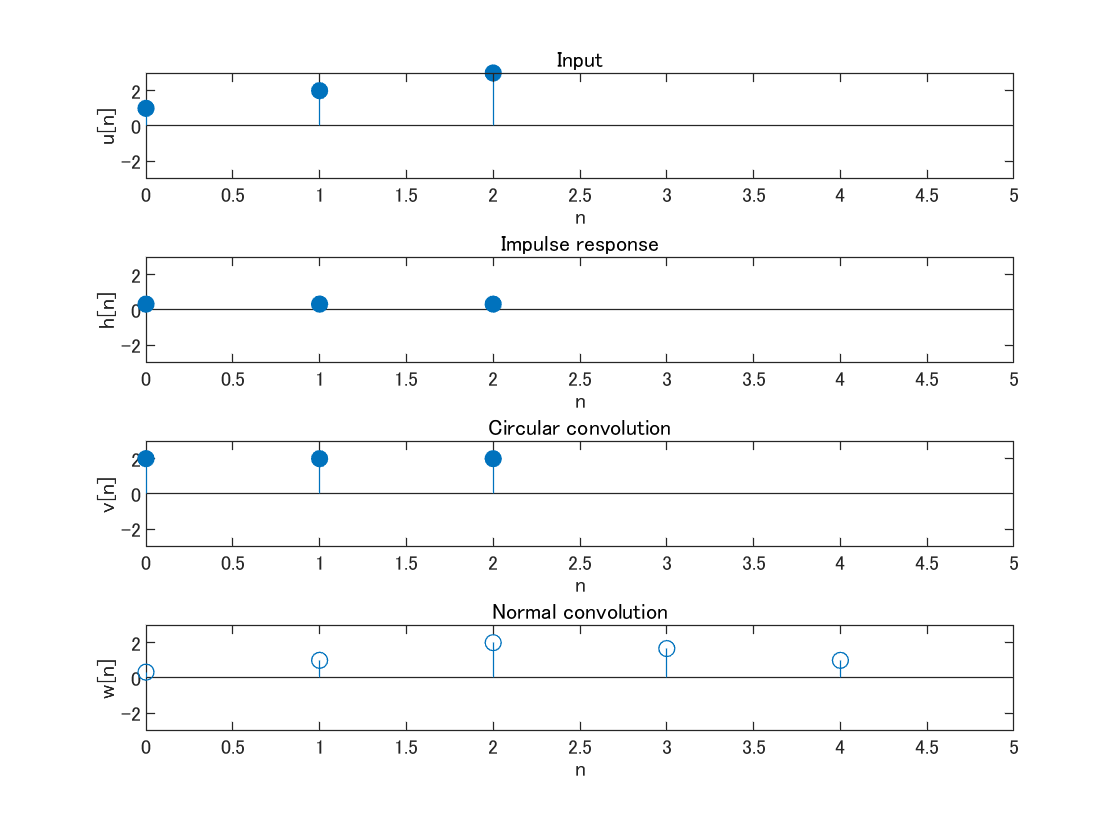

% Normal convolution
w = conv(h,u);

% Lengths of u, h, x and v
nu = length(u);
nh = length(h);
nv = length(v);
nw = length(w);

% Display sequences
figure(1)
nx = max(length(v),length(w));
amax = max(max(abs(u)),max(abs(v)));
% u[n]
subplot(4,1,1)
stem(0:nu-1,u,'filled')
axis([0 nx -amax amax])
xlabel('n')
ylabel('u[n]')
title('Input')
% h[n]
subplot(4,1,2)
stem(0:nh-1,h,'filled')
axis([0 nx -amax amax])
xlabel('n')
ylabel('h[n]')
title('Impulse response')
% v[n]
subplot(4,1,3)
stem(0:nv-1,v,'filled')
axis([0 nx -amax amax])
xlabel('n')
ylabel('v[n]')
title('Circular convolution')
% w[n]
subplot(4,1,4)
stem(0:nw-1,w)
axis([0 nx -amax amax])
xlabel('n')
ylabel('w[n]')
title('Normal convolution')

#### 通常の畳み込みと循環畳み込みが一致する条件

(The condition that normal convolution and circular convolution match)

        
$$L_\mathrm{v}=L_\mathrm{h}+L_\mathrm{u}-1\leq N$$


ただし、(where)

- $L_\mathrm{v}$: 出力の長さ (Output length)

- $L_\mathrm{h}$: インパルス応答の長さ (Length of impulse response)

- $L_\mathrm{u}$: 入力の長さ (Input length)

% Adjusting the lengths
mymse = @(x,y) mean((double(x)-double(y)).^2,'all');
if nv > nw
    wc = [w(:); zeros(nv-nw,1)];
    vc = v(:);
else
    vc = [v(:); zeros(nw-nv,1)];
    wc = w(:);
end
% Check the condition
if (nw <= nPeriod)
    msg = 'TRUE';
else
    msg = 'FALSE (Increse # of zeros for padding)';
end
fprintf('Condition for CCONV to match CONV: \n\t %s', msg)

Condition for CCONV to match CONV: 
	 FALSE (Increse # of zeros for padding)

% MSE
fprintf('MSE: %f', mymse(vc,wc))

MSE: 1.511111

### 入力信号 $\{u[n]\}_n
$ のDFT

(DFT of input signal $\{u[n]\}_n
$)

        
$$U[k]=\sum_{n=0}^{N-1} u[n] W_{N}^{n k}, k\in\{0,1,2,\cdots,N-1\}
$$


ただし，(where)

        
$$W_N=e^{-\j\frac{2\pi}{N}}$$


% DFT of u[n]
U = fft(u,nPeriod);

### フィルタ $\{h[n]\}_n
$ のDFT

(DFT of impulse response $\{h[n]\}_n
$)

        
$$H[k]=\sum_{n=0}^{N-1} h[n] W_{N}^{n k}, k\in\{0,1,2,\cdots,N-1\}
$$


% DFT of h[n]
H = fft(h,nPeriod);

### 出力信号 $\{v[n]\}_n
$ のDFT

(DFT of output signal $\{v[n]\}_n
$)

        
$$V[k]=\sum_{n=0}^{N-1} v[n] W_{N}^{n k}, k\in\{0,1,2,\cdots,N-1\}
$$


% Frequency response of v[n]
V = fft(v,nPeriod);

### DFTの表示

(Display of DFTs)

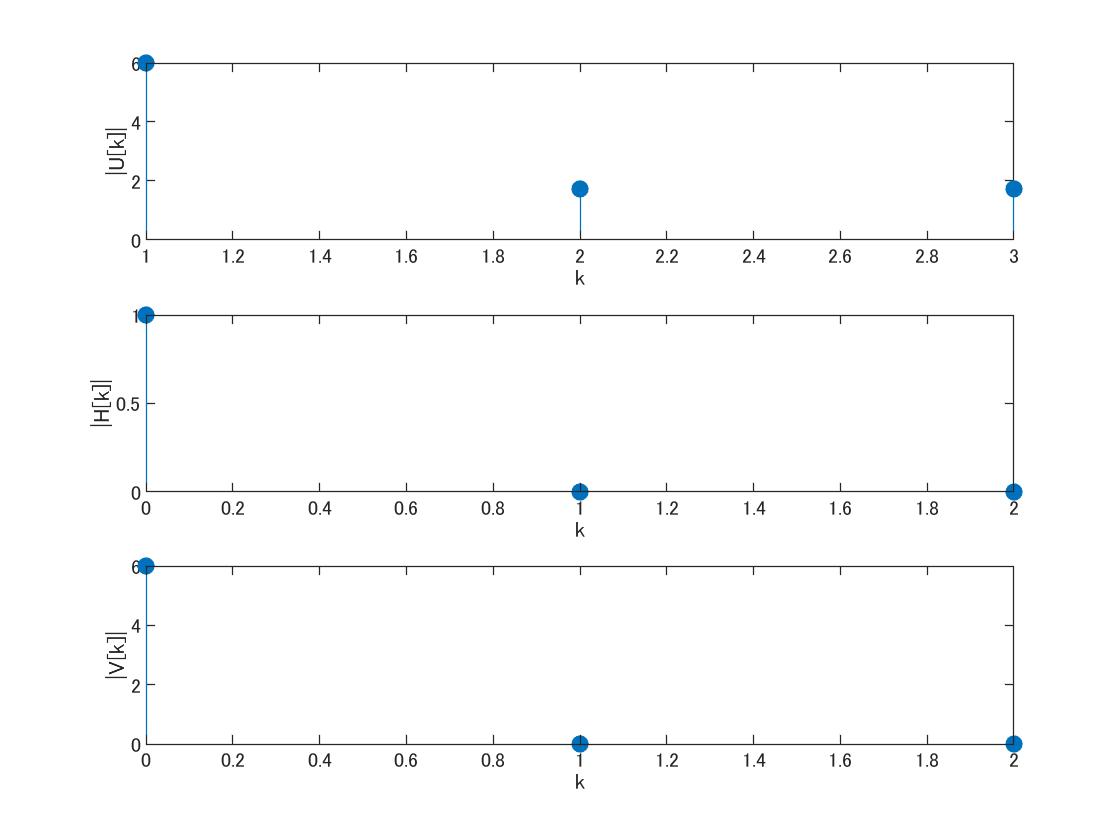

% DFT index
k = 0:nPeriod-1;

% Display of DFTs
figure(2)
subplot(3,1,1)
stem(abs(U),'filled')
xlabel('k')
ylabel('|U[k]|')
subplot(3,1,2)
stem(k,abs(H),'filled')
xlabel('k')
ylabel('|H[k]|')
subplot(3,1,3)
stem(k,abs(V),'filled')
xlabel('k')
ylabel('|V[k]|')

### DFT積

(DFT product)

        
$$V[k]=H[k]U[k],\ k\in\{0,1,2,\cdots,N-1\}$$


循環畳み込みとの比較 (Comparison with circular convolution)

% IDFT of DFT product
y = ifft(H.*U);
% MSE with the cconv result 'v'
fprintf('MSE: %f', mymse(v,y))

MSE: 0.000000

© Copyright, Shogo MURAMATSU, All rights reserved.